# Basic ISETBio and Image Reconstruction Calculation

## Generate a retina with human optics and cone mosaic

% load the display setup
display = load('display.mat');

% 1.0 deg mosaic with a pupil size of 2.5 mm
retina = ConeResponse('eccBasedConeDensity', true, 'eccBasedConeQuantal', true, ...
    'fovealDegree', 1.0, 'display', display.CRT12BitDisplay, 'pupilSize', 2.0);

Create cone moasic object: 
Will do 3 passes
[PASS:  0/ 0]. Adjusting cones between 0.00 225.00 using posDiffTolerange: 0.200000

Hex grid adjustment: on iteration 0 ... 
Hex grid adjustment: on iteration 1 ... 
Hex grid adjustment: on iteration 2 ... 
Hex grid adjustment: on iteration 3 ... 
Hex grid adjustment: on iteration 4 ... 
Hex grid adjustment: on iteration 5 ... 
Hex grid adjustment: on iteration 6 ... 
Hex grid adjustment: on iteration 7 ... 
Hex grid adjustment: on iteration 8 ... 
Hex grid adjustment: on iteration 9 ... 
Hex grid adjustment: on iteration 10 ... 
Hex grid smoothing finished.
Did not converge, but exceeded max number of iterations (10).
Max(movement) in last iteration: 0.666476, Tolerange: 0.001000
Number of Delaunay triangulations: 11
[PASS:  1/ 3]. Adjusting cones between 225.00 229.96 using posDiffTolerange: 0.200000

Hex grid adjustment: on iteration 0 ... 
Hex grid adjustment: on iteration 1 ... 
Hex grid adjustment: on iteration 2 ... 
Hex grid adjustm

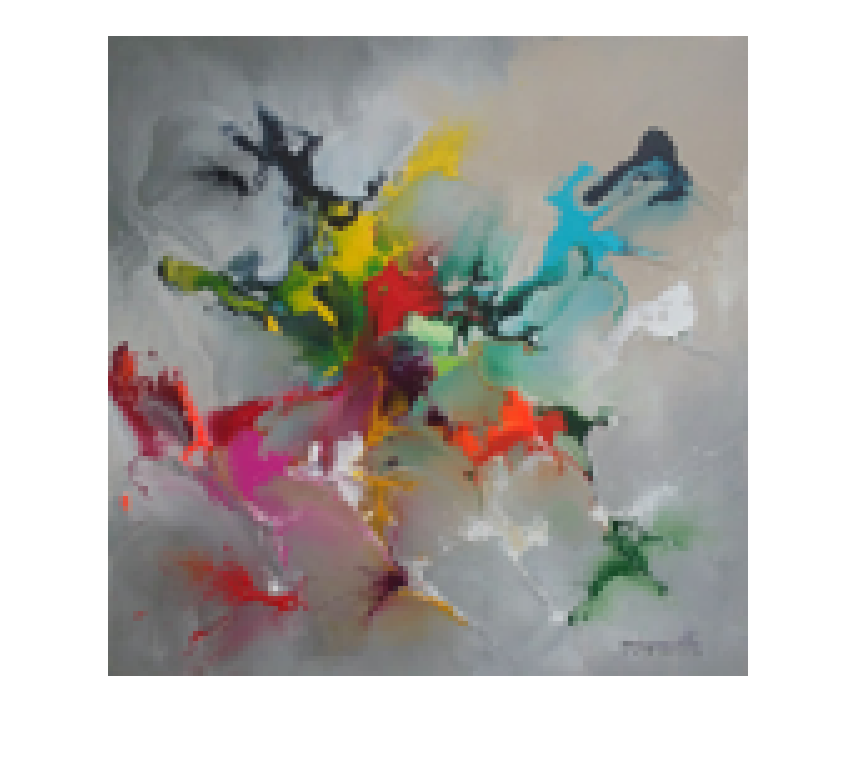

% load an example image
imageSize = [128, 128, 3];
image = im2double(imread('images/2.jpeg'));
image = imresize(image, imageSize(1) / size(image, 1));

% normalize to insure pixels are in the range of [0, 1]
image = (image - min(image(:)));
image = image ./ max(image(:));

assert(min(image(:)) >= 0);
assert(max(image(:)) <= 1);

figure();
imshow(image, 'InitialMagnification', 500);

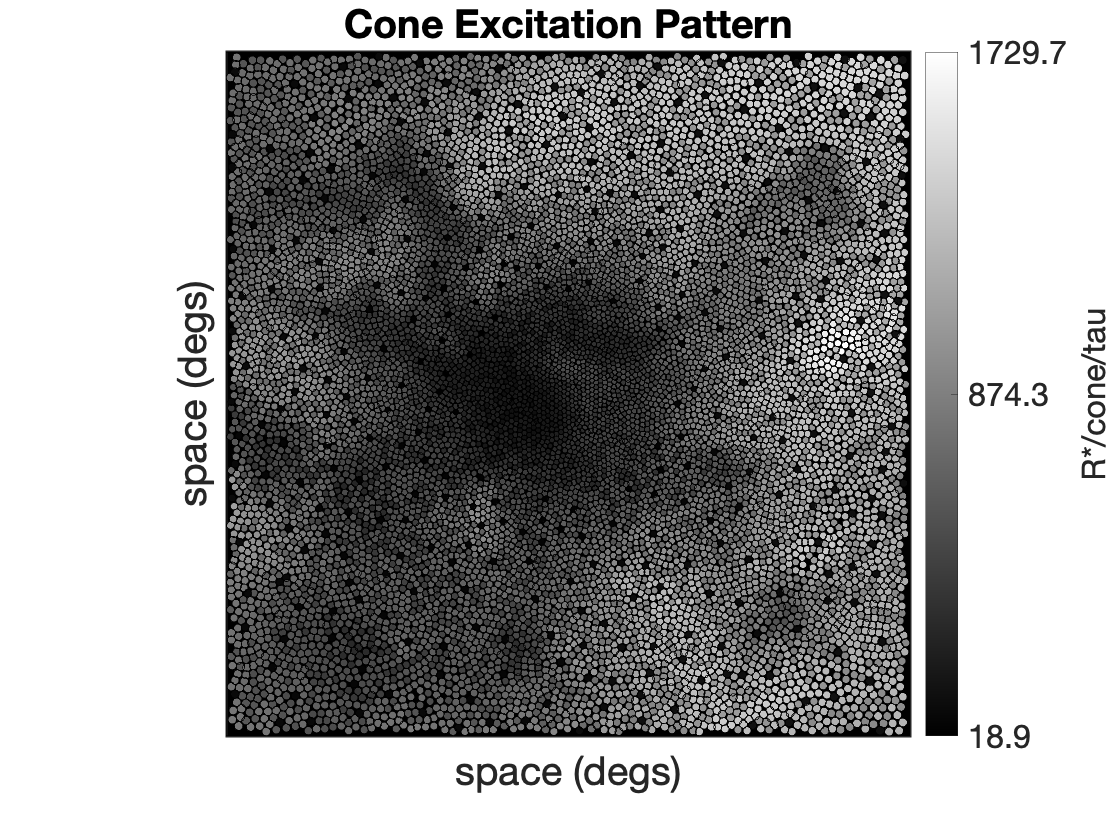

% demo of compute cone responses:

% excitation is a 2D map of cone excitation
% allCone is a vector of cone excitation
% linearImage is the input image after display gamma function

% see ConeResponse class for detailed documentation
[excitation, ~, linearImage, allCone] = retina.compute(image);

% show optical image (OI) and cone excitation
figure();
retina.visualizeExcitation();

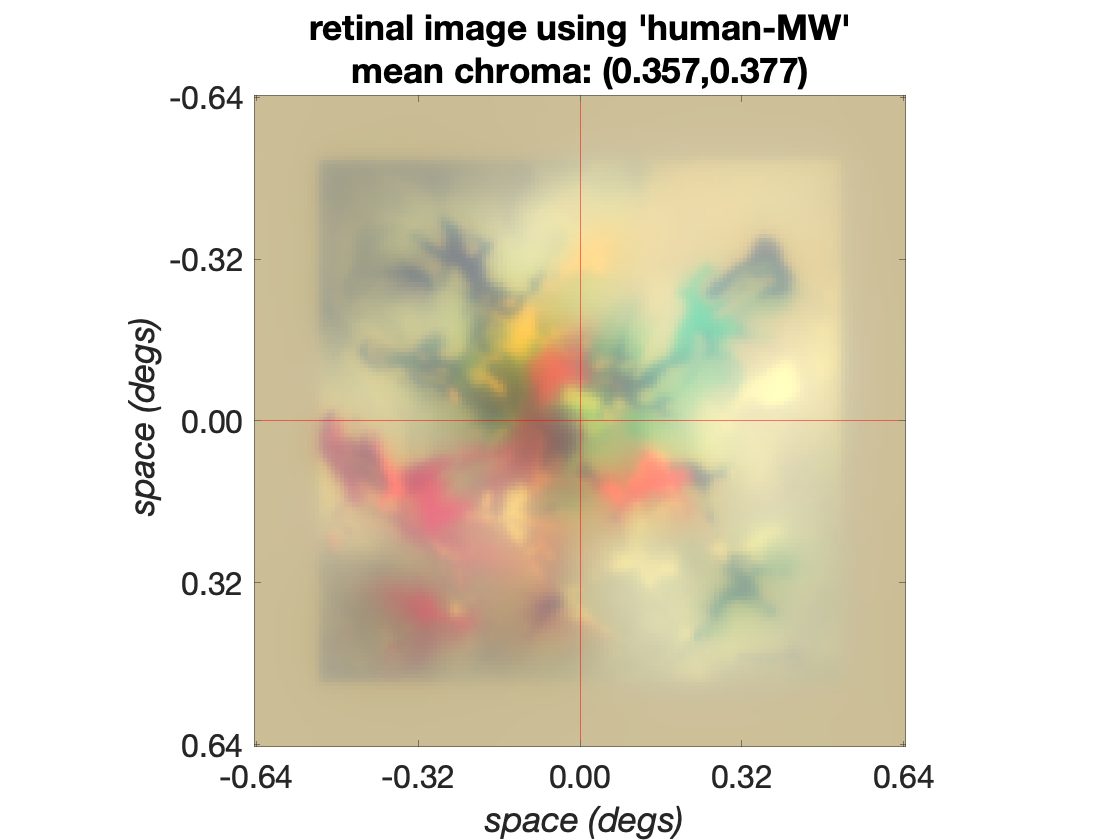

figure();
retina.visualizeOI();

Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 4).


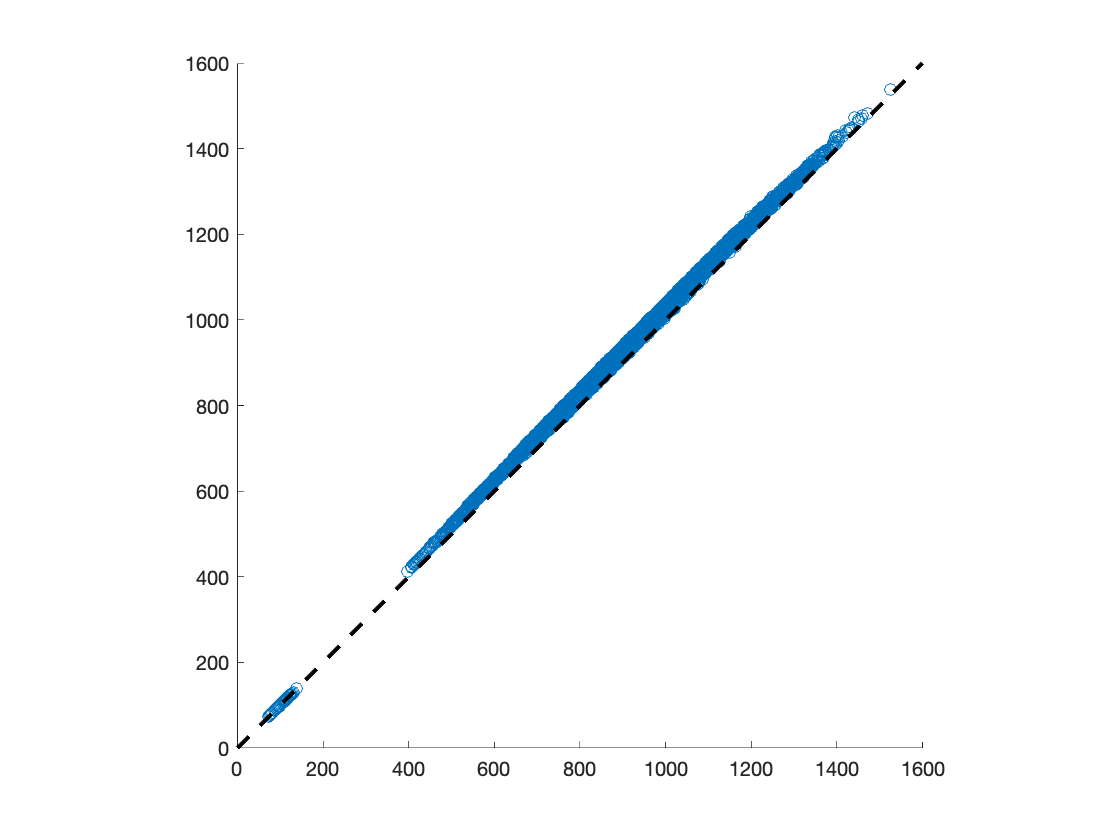

% compute render matrix to represent the
% ISETBio calculation as a linear transformation
% the render matrix is used for likelihood computation
% in image reconstruction (see Methods)

% note that this process is computation-intense
% reduce image size and retina mosaic size (deg)
% if you would like the process to be faster
render = retina.forwardRender(imageSize);

render = double(render);

## Image reconstruction from simulated cone responses

% compute (noise-free) avearge cone response
response = render * linearImage(:);

% cone response with added Poisson noise
response = poissrnd(response);

% construct image estimator
prior = load('sparsePrior.mat');
regPara = 1e-2; stride = 4; nIter = 500; bounded = true; display = 'iter';

estimator = PoissonSparseEstimator(render, inv(prior.regBasis), prior.mu', regPara, stride, imageSize);

% estimate images
% computation intense if large image size and cone mosaic is used
reconImage = estimator.estimate(response, nIter, rand([prod(imageSize), 1]), bounded, 1.0, display);

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -4.840793e+07    0.000e+00    1.089e+03
    1       2   -4.943709e+07    0.000e+00    9.524e+02    3.101e+01
    2       3   -4.944769e+07    0.000e+00    9.501e+02    3.421e-01
    3       4   -4.950524e+07    0.000e+00    9.350e+02    1.784e+00
    4       5   -4.954704e+07    0.000e+00    9.230e+02    1.279e+00
    5       6   -4.962265e+07    0.000e+00    8.986e+02    2.329e+00
    6       7   -4.966205e+07    0.000e+00    8.827e+02    1.225e+00
    7       8   -4.970371e+07    0.000e+00    8.673e+02    1.315e+00
    8       9   -4.975962e+07    0.000e+00    8.397e+02    1.824e+00
    9      10   -4.979801e+07    0.000e+00    8.203e+02    1.299e+00
   10      11   -4.982545e+07    0.000e+00    8.060e+02    9.586e-01
   11      12   -4.988650e+07    0.000e+00    7.706e+02    2.232e+00
   12      13   -4.990494e+07    0.000e+00    7

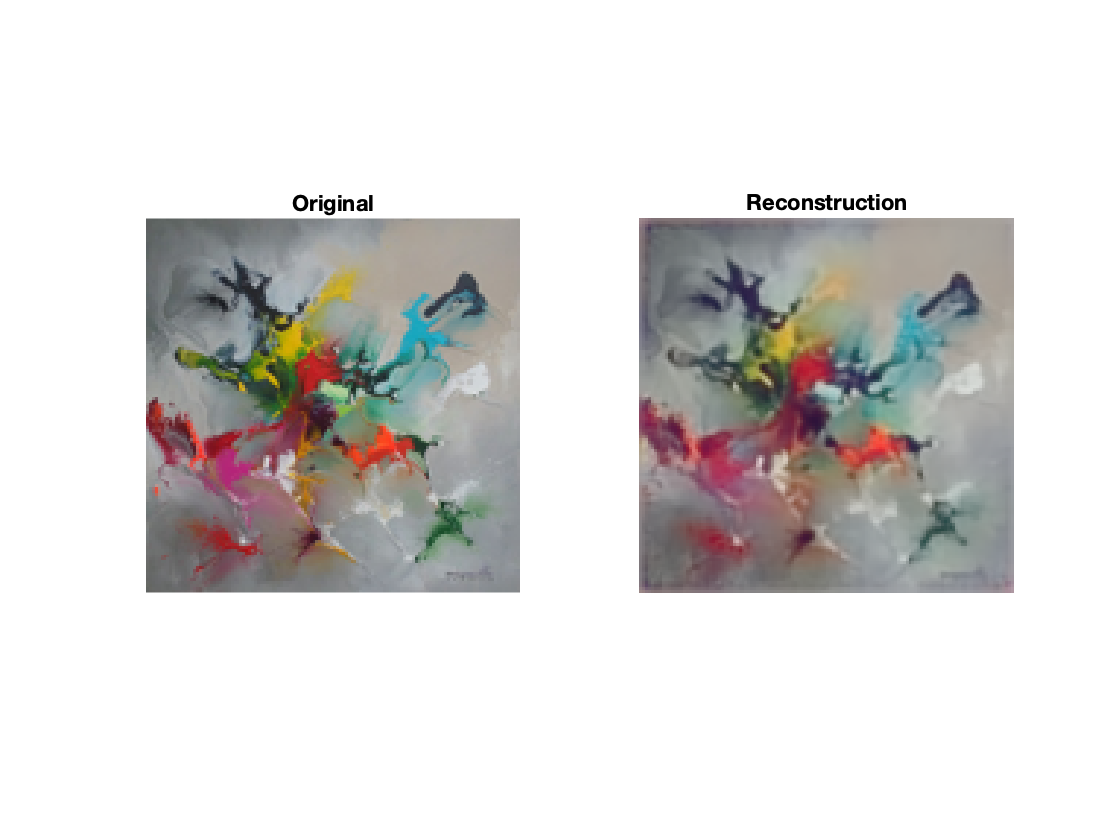

% compare the original and reconstructed images
figure();
subplot(1, 2, 1);
imshow(image, 'InitialMagnification', 500);
title('Original')

% reconstructed image is in linear pixel space
% convert it back to RGB space
recon = gammaCorrection(reconImage, display.CRT12BitDisplay);
subplot(1, 2, 2);
imshow(recon, 'InitialMagnification', 500);
title('Reconstruction')